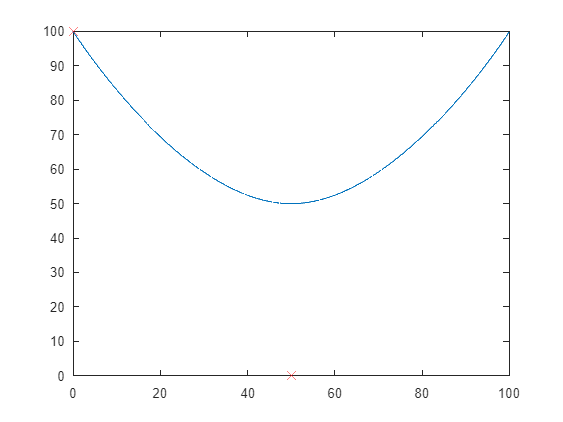

%24/02/2024 Working B Spline Derivatives
%Control Points
P1 = [0, 100];
P2 = P1;
P3 = [50, 0];
P4 = [100, 100];
P5 = P4;
CP = [P1, P2, P3, P4, P5];
%Knot Vector
kn1 = 0.00;
kn2 = 0.01;
kn3 = 0.02;
kn4 = 0.03;
kn5 = 30;
kn6 = 59.97;
kn7 = 59.98;
kn8 = 59.99;
kn9 = 60;
knot = [kn1, kn2, kn3, kn4, kn5, kn6, kn7, kn8, kn9];
vpmin = kn4;
vpmax = kn6;
knotpointx = [];
knotpointy = [];
%Curve Parameters
pmin = 0;
pmax = 60;
pstep = 0.01;
%Array Prealocation
stackx = [];
stacky = [];
stepcount = [];
%step counter
counter = 0;
scountdiv = 5;
svectx = [];
svecty = [];
sdivvect = [];

sflag = ((kn9-kn1)/pstep)/scountdiv;
slfag = ceil(sflag);
for p = pmin:pstep:pmax
    if p >= vpmin
        if p<=vpmax
            counter = counter + 1;
            stepcount = [stepcount; counter];
            [NKPx, NKPy] = NXK4(p, knot, CP);
            stackx = [stackx; NKPx];
            stacky = [stacky; NKPy];
            if counter > 1
                if floor(counter/sflag) == counter/sflag
                    svectx = [svectx; NKPx];
                    svecty = [svecty; NKPy];
                    sdivvect = [sdivvect; counter];
                end
            end
            if (p==kn1)||(p==kn2)||(p==kn3)||(p==kn4)||(p==kn5)||(p==kn6)||(p==kn7)||(p==kn8)||(p==kn9)
                knotpointx = [knotpointx; NKPx];
                knotpointy = [knotpointy; NKPy];
            end
        end
    end
end

%1st Derivative
Q1 = (P2-P1)*3/(kn5-kn2);
Q2 = (P3-P2)*3/(kn6-kn3);
Q3 = (P4-P3)*3/(kn7-kn4);
Q4 = Q3;
QP = [Q1, Q2, Q3, Q4];
vkn1 = kn2;
vkn2 = kn3;
vkn3 = kn4;
vkn4 = kn5;
vkn5 = kn6;
vkn6 = kn7;
vkn7 = kn8;
vknot = [vkn1, vkn2, vkn3, vkn4, vkn5, vkn6, vkn7];
validvmin = vkn3;
validvmax = vkn5;
vmin = pmin;
vmax = pmax;
vvmin = vkn3;
vvmax = vkn5;
vstep = pstep;
vstackx = [];
vstacky = [];
vsvectx = [];
vsvecty = [];
vabs = [];
vsvectcomb = [];
vsdivvect = [];
vknotpointx = [];
vknotpointy = [];
vknotpointcomb = [];
vstepcount = [];
vsknotvect = [];
vcombvect = [];

counter = 0;
stepcount = 0;
sflag = ((vkn7-vkn1)/vstep)/scountdiv;
sflag = ceil(sflag);
for v = vmin:vstep:vmax
    if v >= vvmin
        if v<=vvmax
            counter = counter + 1;
            vstepcount = [vstepcount; counter];
            [NKVx, NKVy] = VXK3(v, vknot, QP);
            vstackx = [vstackx; NKVx];
            vstacky = [vstacky; NKVy];
            abs = sqrt(NKVx^2+NKVy^2);
            vabs = [vabs; abs, counter];
            vcomb = sqrt(NKVx^2+NKVy^2);
            vcombvect = [vcombvect; vcomb];
            if counter > 1
                if floor(counter/sflag) == counter/sflag
                    vsvectx = [vsvectx; NKVx];
                    vsvecty = [vsvecty; NKVy];
                    vsvectcomb = [vsvectcomb; vcomb];
                    vsdivvect = [vsdivvect; counter];
                end
            end
            if (v==vkn1)||(v==vkn2)||(v==vkn3)||(v==vkn4)||(v==vkn5)||(v==vkn6)||(v==vkn7)
                vknotpointx = [vknotpointx; NKVx];
                vknotpointy = [vknotpointy; NKVy];
                vknotpointcomb = [vknotpointcomb; vcomb];
                vsknotvect = [vsknotvect; counter];
            end
        end
    end
end

%Display Control Points
CPx = [P1(1,1), P2(1,1), P3(1,1)];
CPy = [P1(1,2), P2(1,2), P3(1,2)];
%Path Curve
plot(stackx, stacky)
hold on
%Points
scatter(CPx, CPy, 100, "red", "X")
%scatter(svectx, svecty, 80, "blue", "X")
%scatter(knotpointx, knotpointy, 80, "black", "X")
hold off

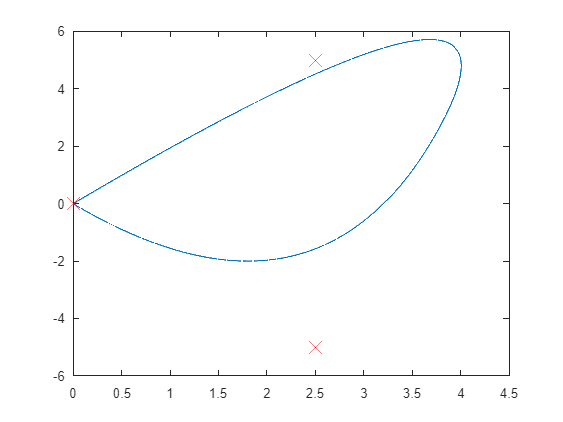

%Display Q Points
QPx = [Q1(1,1), Q2(1,1), Q3(1,1)];
QPy = [Q1(1,2), Q2(1,2), Q3(1,2)];
%dy dx curve
plot(vstackx, vstacky)
hold on
scatter(QPx, QPy, 200, "red", "X")
%scatter(vsvectx, vsvecty, 80, "blue", "X")
%scatter(vknotpointx, vknotpointy, 80, "black", "X")
hold off

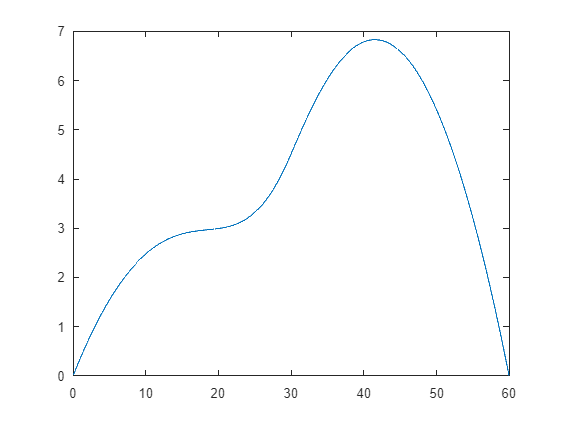

plot(vabs(:,2)/100, vabs(:,1))

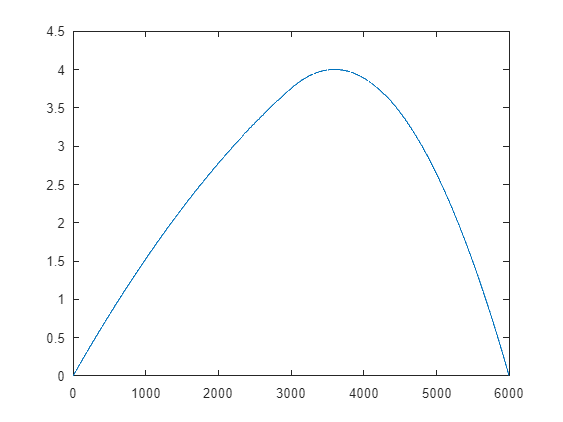

%Velocity Curves
plot(vstepcount, vstackx)
hold on
%scatter(vsdivvect, vsvectx, 80, "blue", "X")
%scatter(vsknotvect, vknotpointx, 80, "black", "X")
hold off

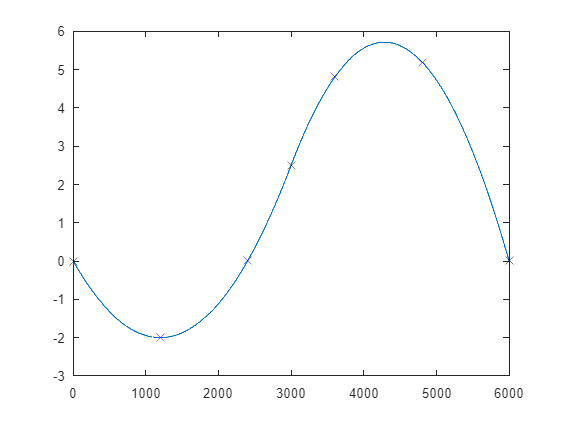

plot(vstepcount, vstacky)
hold on
scatter(vsdivvect, vsvecty, 80, "blue", "X")
scatter(vsknotvect, vknotpointy, 80, "black", "X")
hold off

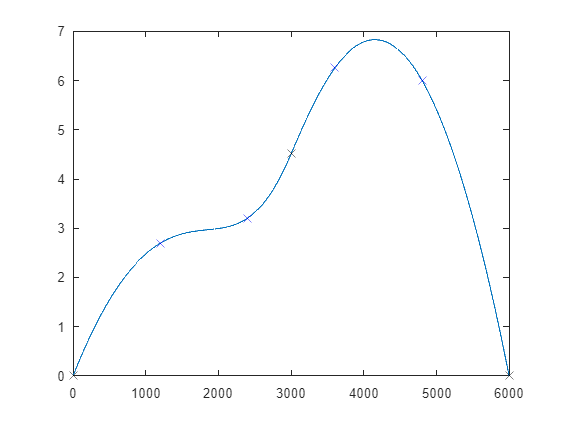

%Combined Velocity
plot(vstepcount, vcombvect)
hold on
scatter(vsdivvect, vsvectcomb, 80, "blue", "X")
scatter(vsknotvect, vknotpointcomb, 80, "black", "X")
hold off

function [SumVPx, SumVPy] = VXK3(v, vknot, QP)

    Q1(1,1) = QP(1,1);
    Q1(1,2) = QP(1,2);
    Q2(1,1) = QP(1,3);
    Q2(1,2) = QP(1,4);
    Q3(1,1) = QP(1,5);
    Q3(1,2) = QP(1,6);
    Q4(1,1) = QP(1,7);
    Q4(1,2) = QP(1,8);

    v1 = vknot(1,1);
    v2 = vknot(1,2);
    v3 = vknot(1,3);
    v4 = vknot(1,4);
    v5 = vknot(1,5);
    v6 = vknot(1,6);

    if (v1<=v)
        if (v<v2)
            V1k1 = 1;
        else
            V1k1 = 0;
        end
    else
        V1k1 = 0;
    end
    if (v2<v)
        if (v<v3)
            V2k1 = 1;
        else
            V2k1 = 0;
        end
    else
        V2k1 = 0;
    end
    if (v3<=v)
        if (v<v4)
            V3k1 = 1;
        else
            V3k1= 0;
        end
    else
        V3k1 = 0;
    end
    if (v4<=v)
        if (v<v5)
            V4k1 = 1;
        else
            V4k1 = 0;
        end
    else
        V4k1 = 0;
    end
    if (v5<=v)
        if (v<v6)
            V5k1 = 1;
        else
            V5k1 = 0;
        end
    else
        V5k1 = 0;
    end

    V1k2 = ((v-v1)/(v2-v1))*V1k1 + ((v3-v)/(v3-v2))*V2k1;
    V2k2 = ((v-v2)/(v3-v2))*V2k1 + ((v4-v)/(v4-v3))*V3k1;
    V3k2 = ((v-v3)/(v4-v3))*V3k1 + ((v5-v)/(v5-v4))*V4k1;
    V4k2 = ((v-v4)/(v5-v4))*V4k1 + ((v6-v)/(v6-v5))*V5k1;

    V1k3 = ((v-v1)/(v3-v1))*V1k2 + ((v4-v)/(v4-v2))*V2k2;
    V2k3 = ((v-v2)/(v4-v2))*V2k2 + ((v5-v)/(v5-v3))*V3k2;
    V3k3 = ((v-v3)/(v5-v3))*V3k2 + ((v6-v)/(v6-v4))*V4k2;

    SumVPx = V1k3*Q1(1,1) + V2k3*Q2(1,1) + V3k3*Q3(1,1) + V3k3*Q4(1,1);
    SumVPy = V1k3*Q1(1,2) + V2k3*Q2(1,2) + V3k3*Q3(1,2) + V3k3*Q4(1,2);

end


function [SumNPx, SumNPy] = NXK4(p, knot, CP)

    P1(1,1) = CP(1,1);
    P1(1,2) = CP(1,2);
    P2(1,1) = CP(1,3);
    P2(1,2) = CP(1,4);
    P3(1,1) = CP(1,5);
    P3(1,2) = CP(1,6);
    P4(1,1) = CP(1,7);
    P4(1,2) = CP(1,8);
    P5(1,1) = CP(1,9);
    P5(1,2) = CP(1,10);

    p1 = knot(1,1);
    p2 = knot(1,2);
    p3 = knot(1,3);
    p4 = knot(1,4);
    p5 = knot(1,5);
    p6 = knot(1,6);
    p7 = knot(1,7);
    p8 = knot(1,8);
    p9 = knot(1,9);

    if (p1<=p)
        if (p<p2)
            N1k1 = 1;
        else
            N1k1 = 0;
        end
    else
        N1k1 = 0;
    end
    if (p2<=p)
        if (p<p3)
            N2k1 = 1;
        else
            N2k1 = 0;
        end
    else
        N2k1 = 0;
    end
    if (p3<=p)
        if (p<p4)
            N3k1 = 1;
        else
            N3k1= 0;
        end
    else
        N3k1 = 0;
    end
    if (p4<=p)
        if (p<p5)
            N4k1 = 1;
        else
            N4k1 = 0;
        end
    else
        N4k1 = 0;
    end
    if (p5<=p)
        if (p<p6)
            N5k1 = 1;
        else
            N5k1 = 0;
        end
    else
        N5k1 = 0;
    end
    if (p6<=p)
        if (p<p7)
            N6k1 = 1;
        else
            N6k1 = 0;
        end
    else
        N6k1 = 0;
    end
    if (p7<=p)
        if (p<p8)
            N7k1 = 1;
        else
            N7k1 = 0;
        end
    else
        N7k1 = 0;
    end
    if (p8<=p)
        if (p<p9)
            N8k1 = 1;
        else
            N8k1 = 0;
        end
    else
        N8k1 = 0;
    end

    N1k2 = ((p-p1)/(p2-p1))*N1k1 + ((p3-p)/(p3-p2))*N2k1;
    N2k2 = ((p-p2)/(p3-p2))*N2k1 + ((p4-p)/(p4-p3))*N3k1;
    N3k2 = ((p-p3)/(p4-p3))*N3k1 + ((p5-p)/(p5-p4))*N4k1;
    N4k2 = ((p-p4)/(p5-p4))*N4k1 + ((p6-p)/(p6-p5))*N5k1;
    N5k2 = ((p-p5)/(p6-p5))*N5k1 + ((p7-p)/(p7-p6))*N6k1;
    N6k2 = ((p-p6)/(p7-p6))*N6k1 + ((p8-p)/(p8-p7))*N7k1;
    N7k2 = ((p-p7)/(p8-p7))*N7k1 + ((p9-p)/(p9-p8))*N8k1;

    N1k3 = ((p-p1)/(p3-p1))*N1k2 + ((p4-p)/(p4-p2))*N2k2;
    N2k3 = ((p-p2)/(p4-p2))*N2k2 + ((p5-p)/(p5-p3))*N3k2;
    N3k3 = ((p-p3)/(p5-p3))*N3k2 + ((p6-p)/(p6-p4))*N4k2;
    N4k3 = ((p-p4)/(p6-p4))*N4k2 + ((p7-p)/(p7-p5))*N5k2;
    N5k3 = ((p-p5)/(p7-p5))*N5k2 + ((p8-p)/(p8-p6))*N6k2;
    N6k3 = ((p-p6)/(p8-p6))*N6k2 + ((p9-p)/(p9-p7))*N7k2;

    N1k4 = ((p-p1)/(p4-p1))*N1k3 + ((p5-p)/(p5-p2))*N2k3;
    N2k4 = ((p-p2)/(p5-p2))*N2k3 + ((p6-p)/(p6-p3))*N3k3;
    N3k4 = ((p-p3)/(p6-p3))*N3k3 + ((p7-p)/(p7-p4))*N4k3;
    N4k4 = ((p-p4)/(p7-p4))*N4k3 + ((p8-p)/(p8-p5))*N5k3;
    N5k4 = ((p-p5)/(p8-p5))*N5k3 + ((p9-p)/(p9-p6))*N6k3;

    SumNPx = N1k4*P1(1,1) + N2k4*P2(1,1) + N3k4*P3(1,1) + N4k4*P4(1,1) + N5k4*P5(1,1);
    SumNPy = N1k4*P1(1,2) + N2k4*P2(1,2) + N3k4*P3(1,2) + N4k4*P4(1,2) + N5k4*P5(1,2);
end